%%% READ ME %%%
% Scriptet virker kun på Matlab 2020 og nyere
% Legg ActualSpeedrun mappen i C:\Users\Username\Documents\MATLAB
% VIEW -> HIDE CODE (for beste visning

clearvars
% clear all

addpath('ActualSpeedrun/Funksjoner/') % Legger til folder med funksjoner til matlab path
addpath('ActualSpeedrun/Images') % Legger til folder med bilder i matlab path


# Explode Higher Order ODE's

*(Endre syms i koden under etter hovedvariabel og orden)*

syms x(t) x1(t) x2(t) x3(t) Y1 Y2 % Hovedvariabel er x(t) og de andre er til eksplosjonen

% cond1 = x(0) == 1;
% cond2 = diff(x(0)) == -1;
% conds = [cond1 cond2]
higherOrderODE = 4*t^2*diff(x,2)+12*t*diff(x) +3*x == 0 % Eksempel: diff(x,3)+2*diff(x,2)+4*diff(x) +2*x== 0

$$higherOrderODE(t) = 3\,x\left(t\right)+4\,t^{2}\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+12\,t\,\frac{\partial }{\partial t}x\left(t\right)=0$$

[firstOrderODEs] = odeToVectorField(higherOrderODE)

$$firstOrderODEs = \left(\begin{array}{c} Y_{2}\\ -\frac{3\,\left(4\,t\,Y_{2}+Y_{1}\right)}{4\,t^{2}} \end{array}\right)$$

M = matlabFunction(firstOrderODEs, 'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(2);1.0./t.^2.*(t.*Y(2).*4.0+Y(1)).*(-3.0./4.0)]


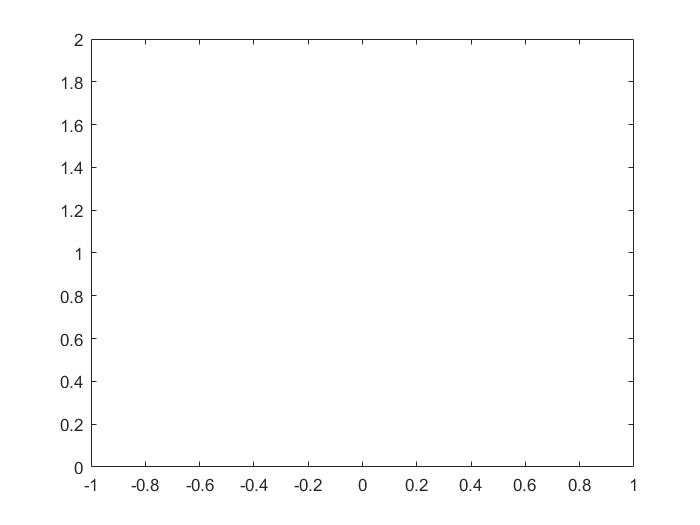

interval = [0 20];
yInit = [1 -1]; % [condition1, condition2,...]
ySolve = ode45(M,interval,yInit);
ySolve.x(1); % Viser solved for x lik...
tValues = linspace(0,20,100);
yValues = deval(ySolve,tValues,1);
plot(tValues,yValues);